**Analysis on BRENDA KM values **

Load data and set graphics and taxa colormap

% graphics
set(groot,'defaultAxesTickLabelInterpreter','latex');  
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

% BRENDA db
load('BRENDAKMdb_nomutants.mat')
dballannotations.SuperClass(isundefined(dballannotations.SuperClass))='Not in NCBI';


% colormap
keySet=cellstr(unique(dballannotations.SuperClass));
valueSet={[127,201,127]/255,...
    [190,174,212]/255,...
    [56,108,176]/255,...
    [253,192,134]/255,...
    [240,2,127]/255,...
    [255,255,153]/255};
colormaptaxa=containers.Map(keySet, valueSet);

Percentile and Median of KM distribution

disp('First quartile')

First quartile


disp(prctile(dballannotations.KM,25))

    0.0240



disp('Median')

Median


disp(prctile(dballannotations.KM,50))

    0.1800



disp('Last quartile')

Last quartile


disp(prctile(dballannotations.KM,75))

    1.3135



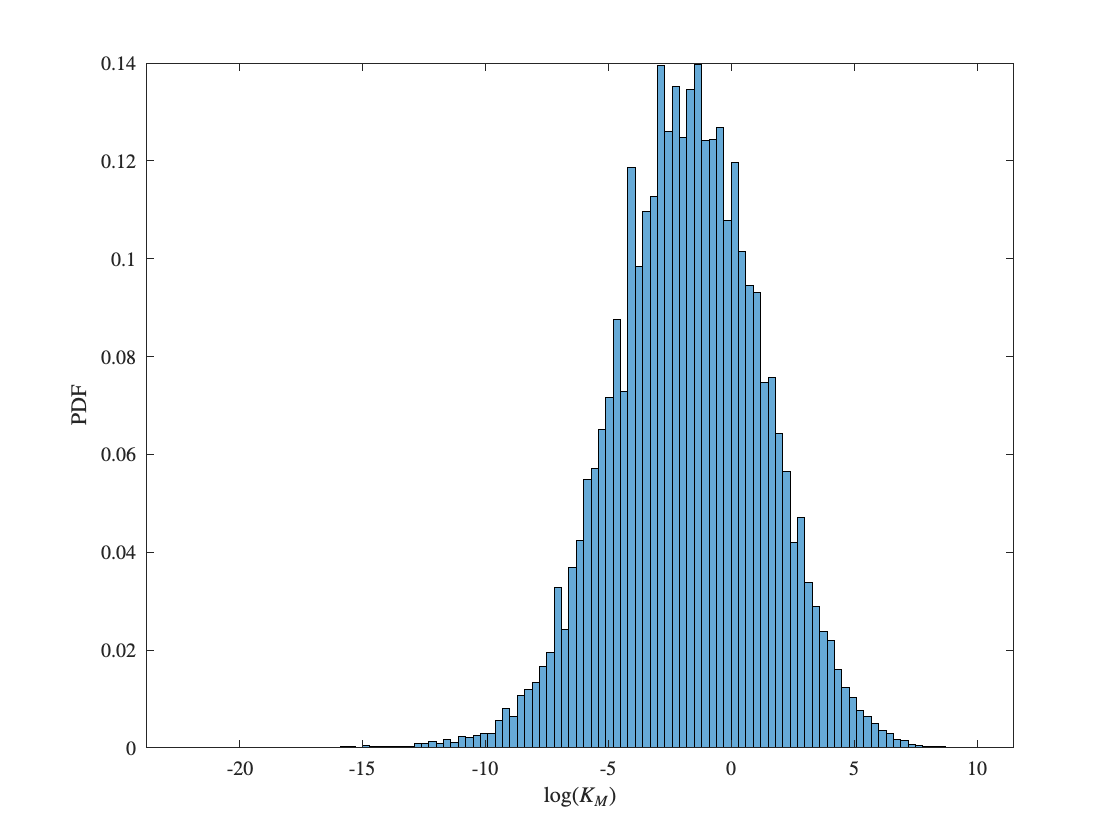


figure, histogram(dballannotations.logKM, 'Normalization', 'pdf')
xlabel('log($K_M$)')
ylabel('PDF')

Remove the substrates with NA, 0, or 'None' InChiKey (when structural information is available)

if sum(strcmp('InChIKey', dballannotations.Properties.VariableNames))
    f1=isundefined(dballannotations.InChIKey);
    f2=(dballannotations.InChIKey=='0');
    f3=(dballannotations.InChIKey=='None');
end


disp('Number of records with NaN inchikey')

Number of records with NaN inchikey


disp(sum(f1))

     3



disp('Number of records with 0 inchikey')

Number of records with 0 inchikey


disp(sum(f2))

        4006



disp('Number of records with None inchikey')

Number of records with None inchikey


disp(sum(f3))

   542




disp('Number of records left')

Number of records left


filtertotal=~(f1|f2|f3);
disp(sum(filtertotal))

       66322




dballannotations_wINCHIKEY=dballannotations(filtertotal,:);

Temperature Dependence

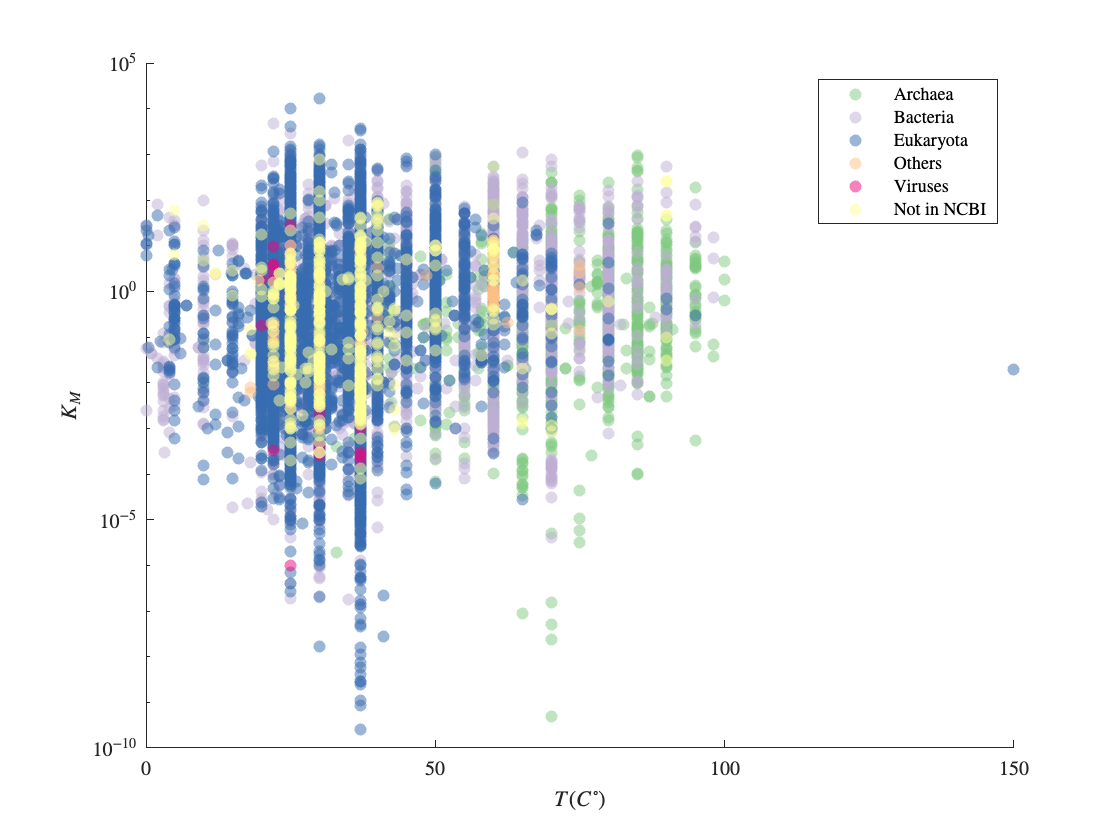

% scatter plot temperature vs Km (ALL)
figure,
for ind=1:length(keySet)
    filter=(dballannotations.SuperClass==keySet{ind});
    if(sum(filter)>0)
        s=scatter(dballannotations.Temperature(filter), dballannotations.KM(filter),[],colormaptaxa(keySet{ind}), 'filled');
        s.MarkerFaceAlpha=0.5;
        hold on
    end
end

set(gca, 'YScale', 'log')
xlabel('$T(C^{\circ})$')
ylabel('$K_M$')
legend(keySet)


disp('Spearman Correlation')

Spearman Correlation


disp(corr(dballannotations.Temperature(~isnan(dballannotations.Temperature)), dballannotations.KM(~isnan(dballannotations.Temperature)), 'type', 'Spearman'))

    0.0927



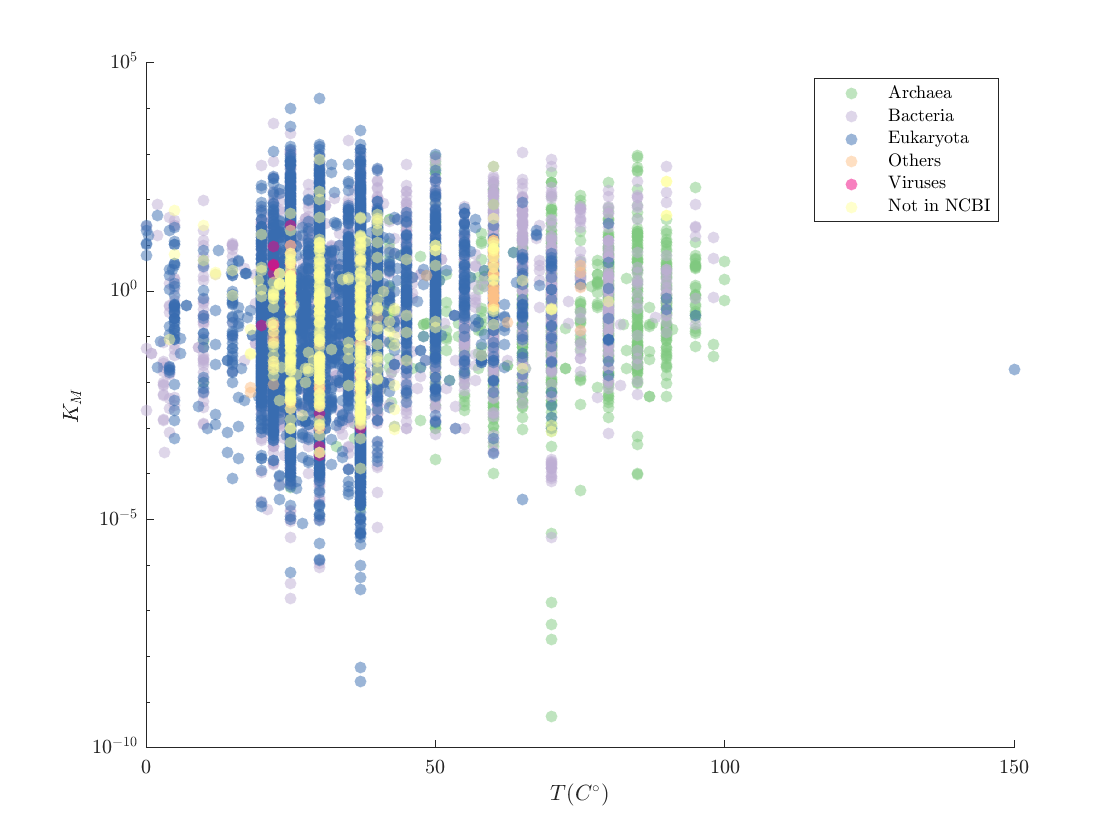


% scatter plot temperature vs Km (substrates with INCHIKEY)
figure,
for ind=1:length(keySet)
    filter=(dballannotations_wINCHIKEY.SuperClass==keySet{ind});
    if(sum(filter)>0)
        s=scatter(dballannotations_wINCHIKEY.Temperature(filter), dballannotations_wINCHIKEY.KM(filter),[],colormaptaxa(keySet{ind}), 'filled');
        s.MarkerFaceAlpha=0.5;
        hold on
    end
end

set(gca, 'YScale', 'log')
xlabel('$T(C^{\circ})$')
ylabel('$K_M$')
legend(keySet)


disp('Spearman Correlation')

Spearman Correlation


disp(corr(dballannotations_wINCHIKEY.Temperature(~isnan(dballannotations_wINCHIKEY.Temperature)), dballannotations_wINCHIKEY.KM(~isnan(dballannotations_wINCHIKEY.Temperature)), 'type', 'Spearman'))

    0.1054





% correlation for different taxa (Temperature)
%taxa="Archaea"
%taxa="Bacteria"
taxa="Eukaryota"

taxa = "Eukaryota"

%taxa="Viruses"

figure,
filter=(dballannotations.SuperClass==taxa);
disp('Number of Records')

Number of Records


disp(sum(filter))

       42950



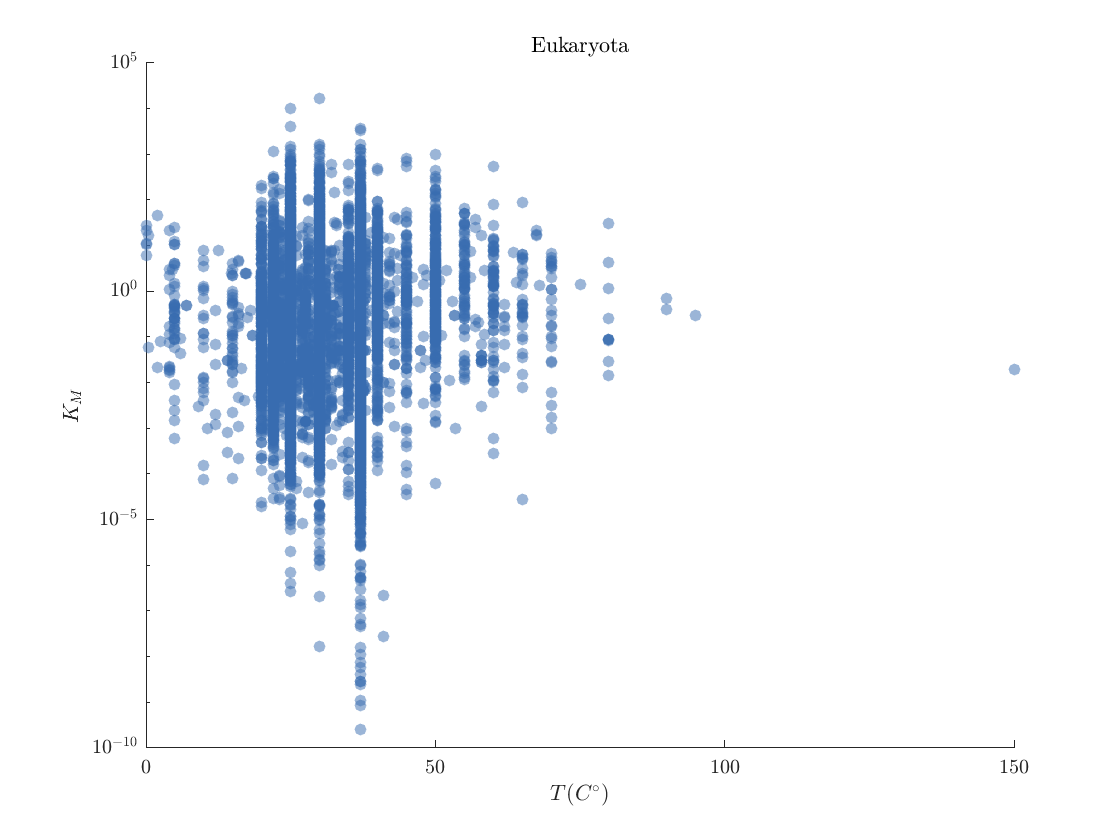

s=scatter(dballannotations.Temperature(filter), dballannotations.KM(filter),[],colormaptaxa(taxa), 'filled');
s.MarkerFaceAlpha=0.5;


set(gca, 'YScale', 'log')
xlabel('$T(C^{\circ})$')
ylabel('$K_M$')
title(taxa)



disp('Spearman Correlation')

Spearman Correlation


dt=dballannotations(filter,:);
disp(corr(dt.Temperature(~isnan(dt.Temperature)), dt.KM(~isnan(dt.Temperature)), 'type', 'Spearman'))

    0.0356



pH Dependence

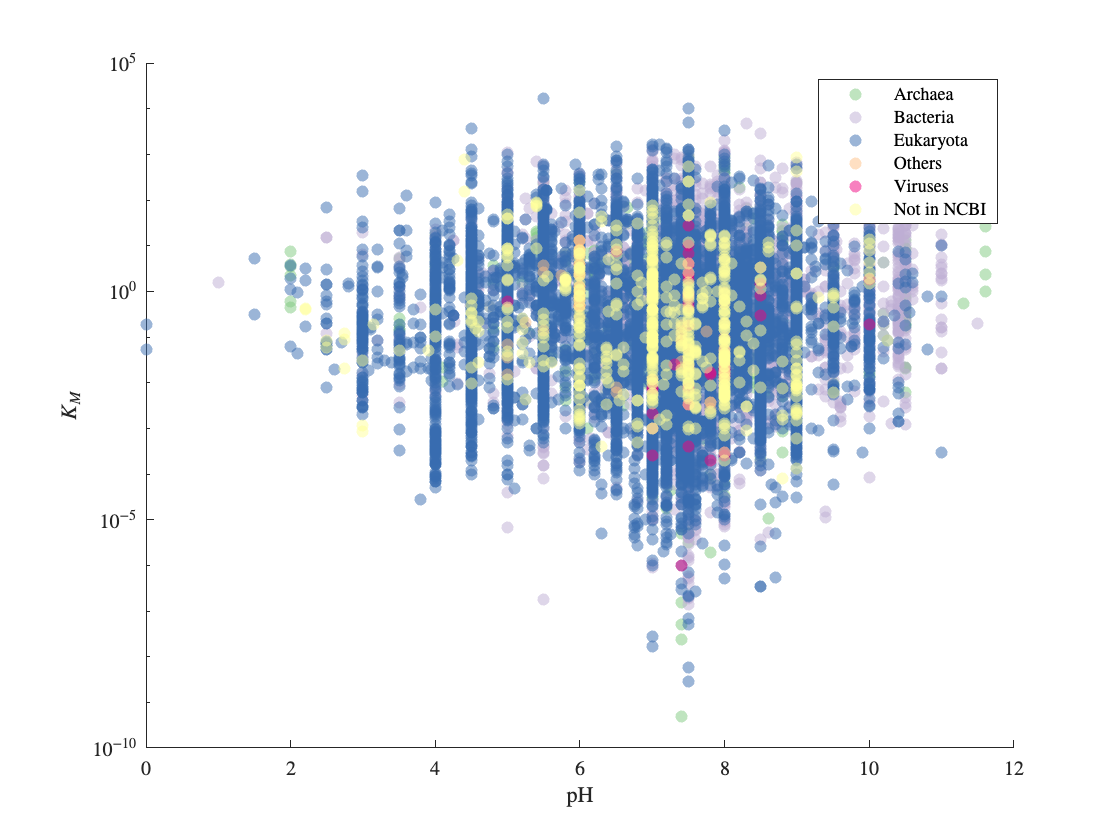

% scatter plot pH vs Km (ALL)
figure,
for ind=1:length(keySet)
    filter=(dballannotations.SuperClass==keySet{ind});
    if(sum(filter)>0)
        s=scatter(dballannotations.pH(filter), dballannotations.KM(filter),[],colormaptaxa(keySet{ind}), 'filled');
        s.MarkerFaceAlpha=0.5;
        hold on
    end
end

set(gca, 'YScale', 'log')
xlabel('pH')
ylabel('$K_M$')
legend(keySet)


disp('Spearman Correlation')

Spearman Correlation


disp(corr(dballannotations.pH(~isnan(dballannotations.pH)), dballannotations.KM(~isnan(dballannotations.pH)), 'type', 'Spearman'))

   -0.0232



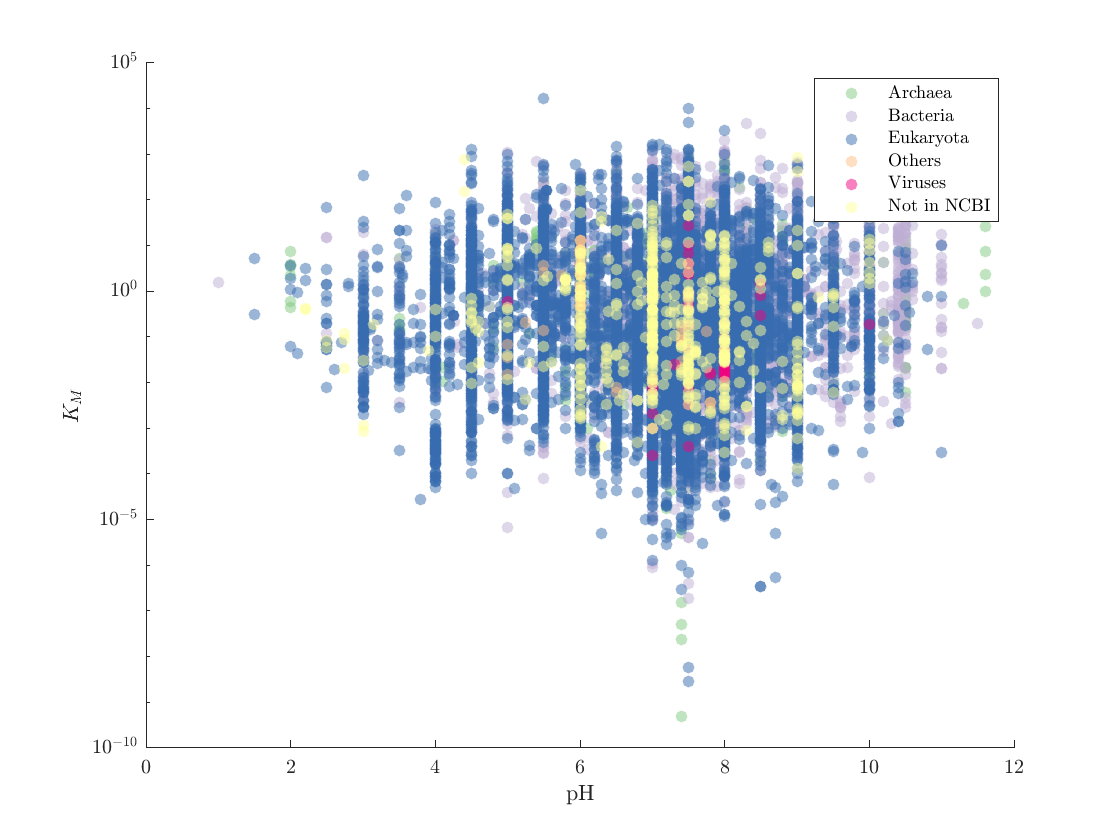


% scatter plot pH vs Km (substrates with INCHIKEY)
figure,
for ind=1:length(keySet)
    filter=(dballannotations_wINCHIKEY.SuperClass==keySet{ind});
    if(sum(filter)>0)
        s=scatter(dballannotations_wINCHIKEY.pH(filter), dballannotations_wINCHIKEY.KM(filter),[],colormaptaxa(keySet{ind}), 'filled');
        s.MarkerFaceAlpha=0.5;
        hold on
    end
end

set(gca, 'YScale', 'log')
xlabel('pH')
ylabel('$K_M$')
legend(keySet)


disp('Spearman Correlation')

Spearman Correlation


disp(corr(dballannotations_wINCHIKEY.pH(~isnan(dballannotations_wINCHIKEY.pH)), dballannotations_wINCHIKEY.KM(~isnan(dballannotations_wINCHIKEY.pH)), 'type', 'Spearman'))

   -0.0177




% correlation for different taxa (pH)
%taxa="Archaea"
%taxa="Bacteria"
taxa="Eukaryota"

taxa = "Eukaryota"

%taxa="Viruses"

figure,
filter=(dballannotations.SuperClass==taxa);
disp('Number of Records')

Number of Records


disp(sum(filter))

       42950



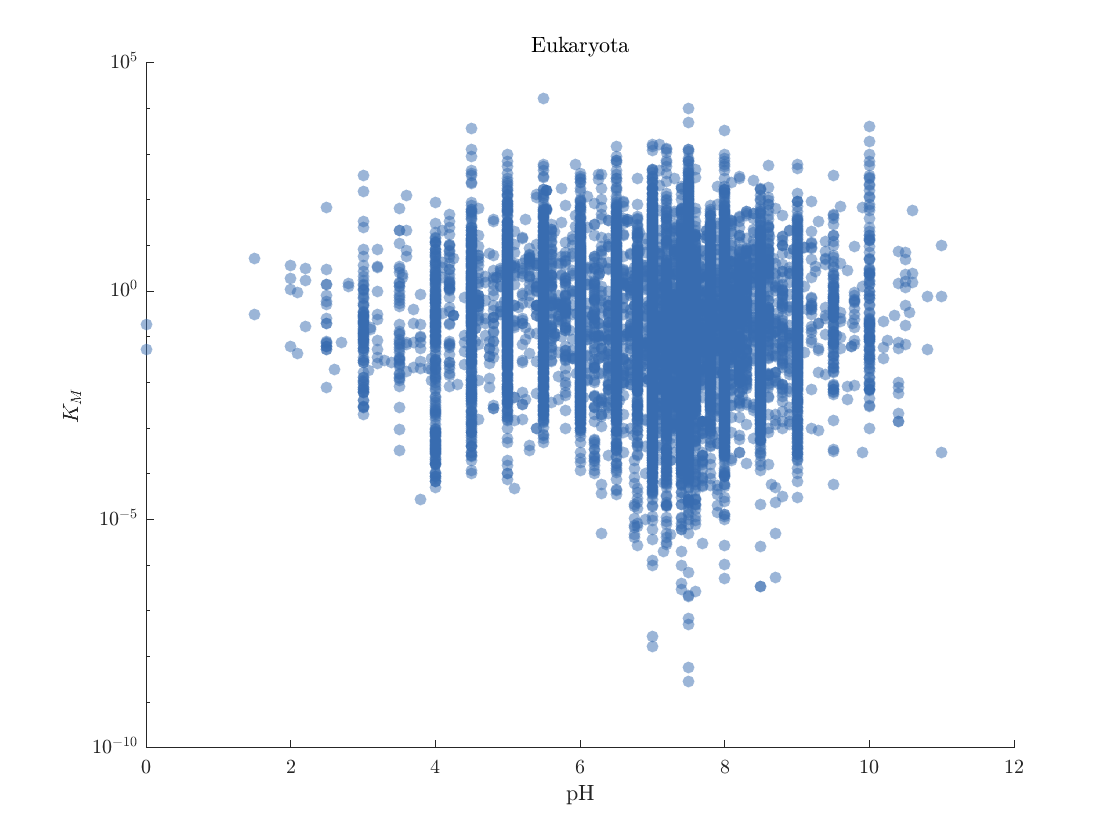

s=scatter(dballannotations.pH(filter), dballannotations.KM(filter),[],colormaptaxa(taxa), 'filled');
s.MarkerFaceAlpha=0.5;


set(gca, 'YScale', 'log')
xlabel('pH')
ylabel('$K_M$')
title(taxa)



disp('Spearman Correlation')

Spearman Correlation


dt=dballannotations(filter,:);
disp(corr(dt.pH(~isnan(dt.pH)), dt.KM(~isnan(dt.pH)), 'type', 'Spearman'))

   -0.0562



Tables with grouping according EC, substrate names

% All the data 
tG = groupcounts(dballannotations,{'EC','substrate'});
tG = sortrows(tG,'GroupCount','descend')

tG = 30151×4 table
       EC                    substrate                  GroupCount    Percent 
    ________    ____________________________________    __________    ________

    4.1.1.39    CO2                                        489         0.68997
    4.1.1.39    O2                                         230         0.32452
    3.2.1.26    sucrose                                    156         0.22011
    3.2.1.21    4-nitrophenyl-beta-D-glucopyranoside       101         0.14251
    1.1.1.1     ethanol                                     93         0.13122
    3.1.3.1     4-nitrophenyl phosphate                     87         0.12275
    3.2.1.21    cellobiose                                  84         0.11852
    1.1.1.27    pyruvate                                    81         0.11429
    1.1.1.37    oxaloacetate                          

% NCBI validated data
dbNCBI=dballannotations(~isundefined(dballannotations.SuperClass),:);
tGNCBI = groupcounts(dbNCBI,{'EC','substrate'});
tGNCBI = sortrows(tGNCBI,'GroupCount','descend')

tGNCBI = 30151×4 table
       EC                    substrate                  GroupCount    Percent 
    ________    ____________________________________    __________    ________

    4.1.1.39    CO2                                        489         0.68997
    4.1.1.39    O2                                         230         0.32452
    3.2.1.26    sucrose                                    156         0.22011
    3.2.1.21    4-nitrophenyl-beta-D-glucopyranoside       101         0.14251
    1.1.1.1     ethanol                                     93         0.13122
    3.1.3.1     4-nitrophenyl phosphate                     87         0.12275
    3.2.1.21    cellobiose                                  84         0.11852
    1.1.1.27    pyruvate                                    81         0.11429
    1.1.1.37    oxaloacetate                      

% Eukariota
dbEukaryota=dballannotations((dballannotations.SuperClass=='Eukaryota'),:);
tGEukaryota = groupcounts(dbEukaryota,{'EC','substrate'});
tGEukaryota = sortrows(tGEukaryota,'GroupCount','descend')

tGEukaryota = 18821×4 table
       EC                              substrate                            GroupCount    Percent
    ________    ________________________________________________________    __________    _______

    4.1.1.39    CO2                                                            460          1.071
    4.1.1.39    O2                                                             225        0.52386
    3.2.1.26    sucrose                                                        127        0.29569
    3.2.1.21    4-nitrophenyl-beta-D-glucopyranoside                            70        0.16298
    3.2.1.21    cellobiose                                                      66        0.15367
    1.1.1.1     ethanol                                                         64        0.14901
    2.5.1.18    1-chloro-2,4-dinitrobenzene        

% Eukariota Not Fungi
dbEukaryotaNotFungi=dballannotations((dballannotations.EukNotFungi=='EukNotFungi'),:);
tGEukaryotaNotFungi = groupcounts(dbEukaryotaNotFungi,{'EC','substrate'});
tGEukaryotaNotFungi = sortrows(tGEukaryotaNotFungi,'GroupCount','descend')

tGEukaryotaNotFungi = 16259×4 table
        EC                               substrate                            GroupCount    Percent
    __________    ________________________________________________________    __________    _______

    4.1.1.39      CO2                                                            460         1.2776
    4.1.1.39      O2                                                             225         0.6249
    1.1.1.1       ethanol                                                         62        0.17219
    1.1.1.27      pyruvate                                                        58        0.16108
    2.5.1.18      1-chloro-2,4-dinitrobenzene                                     58        0.16108
    3.5.4.3       guanine                                                         58        0.16108
    3.2.1.26      sucrose  

Statistics per group

% Measures for All organisms and Euk
tGselAll=groupstatistics(dballannotations,tG);
tGselEuK=groupstatistics(dbEukaryota,tGEukaryota);

% focus on Eukaryota
db=dbEukaryota;
tGsel=tGselEuK;

% % grouping with INCHIKEY
% % All the data 
% tG = groupcounts(dballannotations_wINCHIKEY,{'EC','InChIKey'});
% tG = sortrows(tG,'GroupCount','descend')
% % NCBI validated data
% dbNCBI=dballannotations_wINCHIKEY(~isundefined(dballannotations_wINCHIKEY.SuperClass),:);
% tGNCBI = groupcounts(dbNCBI,{'EC','InChIKey'});
% tGNCBI = sortrows(tGNCBI,'GroupCount','descend')
% % Eukariota
% dbEukaryota=dballannotations_wINCHIKEY((dballannotations_wINCHIKEY.SuperClass=='Eukaryota'),:);
% tGEukaryota = groupcounts(dbEukaryota,{'EC','InChIKey'});
% tGEukaryota = sortrows(tGEukaryota,'GroupCount','descend')
% % Eukariota Not Fungi
% dbEukaryotaNotFungi=dballannotations_wINCHIKEY((dballannotations_wINCHIKEY.EukNotFungi=='EukNotFungi'),:);
% tGEukaryotaNotFungi = groupcounts(dbEukaryotaNotFungi,{'EC','InChIKey'});
% tGEukaryotaNotFungi = sortrows(tGEukaryotaNotFungi,'GroupCount','descend')
% 
% % Measures for All organisms and Euk
% tGselAll=groupstatistics_inchikey(dballannotations_wINCHIKEY,tG);
% tGselEuK=groupstatistics_inchikey(dbEukaryota,tGEukaryota);

Relation between Logarithmic Fluctuations and Number of Organisms

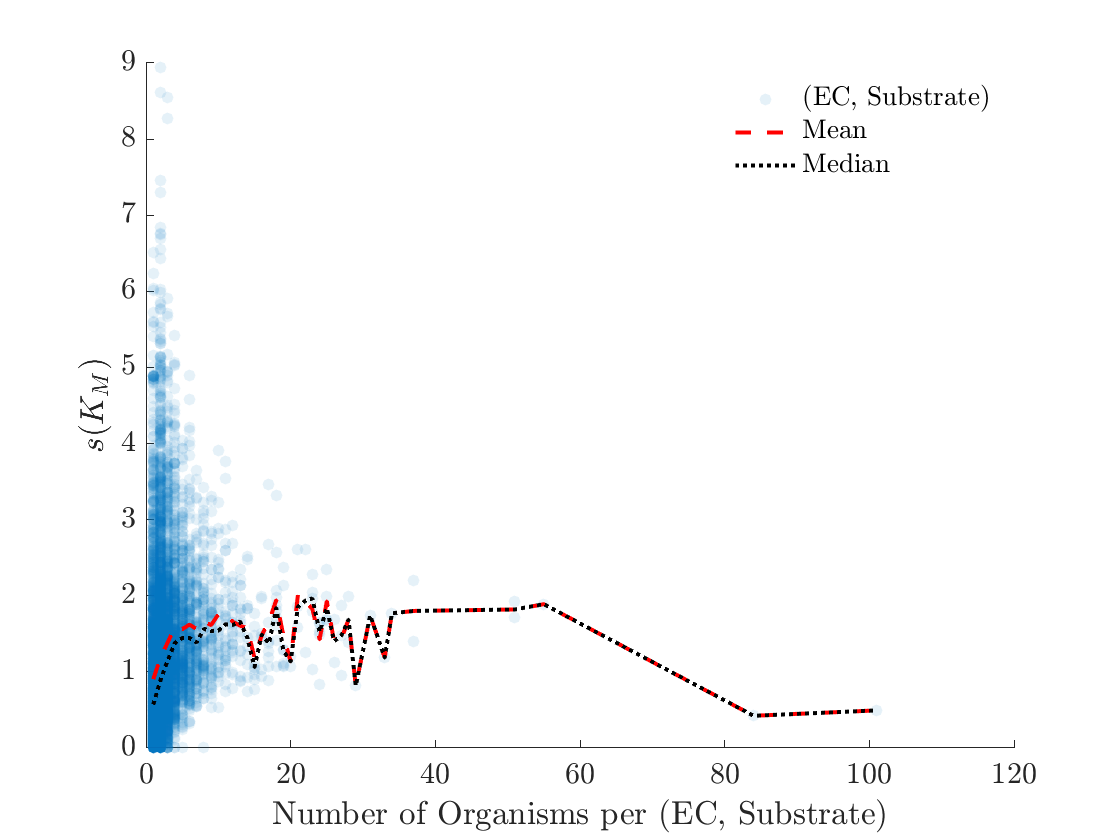

figure,
s=scatter(tGsel.numorganisms(tGsel.GroupCount>1),tGsel.stdlog(tGsel.GroupCount>1),'filled');
s.MarkerFaceAlpha=0.1;

hold on

nou=unique(tGsel.numorganisms);
avgls=zeros(length(nou),1);
for ind=1:length(nou)
 avgls(ind)=mean(tGsel.stdlog(and(tGsel.numorganisms==nou(ind),tGsel.GroupCount>1)));
end
medls=zeros(length(nou),1);
for ind=1:length(nou)
 medls(ind)=median(tGsel.stdlog(and(tGsel.numorganisms==nou(ind),tGsel.GroupCount>1)));
end


p1=plot(nou, avgls, 'r--', 'LineWidth',2);
hold on
p2=plot(nou, medls, 'k:', 'LineWidth',2);



legend('(EC, Substrate)', 'Mean', 'Median')
xlabel('Number of Organisms per (EC, Substrate)')
ylabel('$s(K_M)$')
set(gca, 'FontSize', 15)
legend('boxoff')

Filter on the minimal number of organisms

no=15;

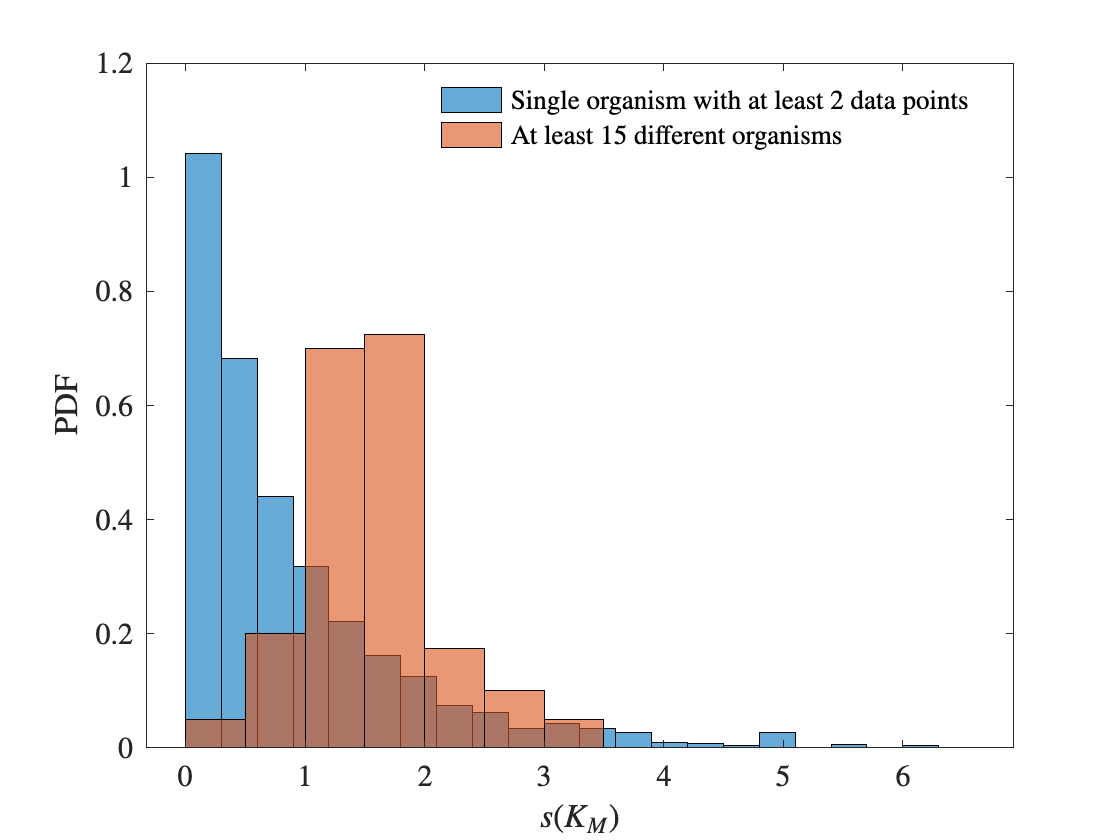

figure,
histogram(tGsel.stdlog(and(tGsel.numorganisms==1,tGsel.GroupCount>1)), 'Normalization', 'PDF')
hold on
histogram(tGsel.stdlog(tGsel.numorganisms>=no), 'Normalization', 'PDF')


legend('Single organism with at least 2 data points', 'At least 15 different organisms')
xlabel('$s(K_M)$')
ylabel('PDF')
set(gca, 'FontSize', 15)
legend('boxoff')

KS statistics and Logarithmic skewness

tGsel_fit=script_fit_KM(tGsel(tGsel.numorganisms>=no,:), db);
tGsel_skew=script_SK_KM(tGsel(tGsel.numorganisms>=no,:), db);

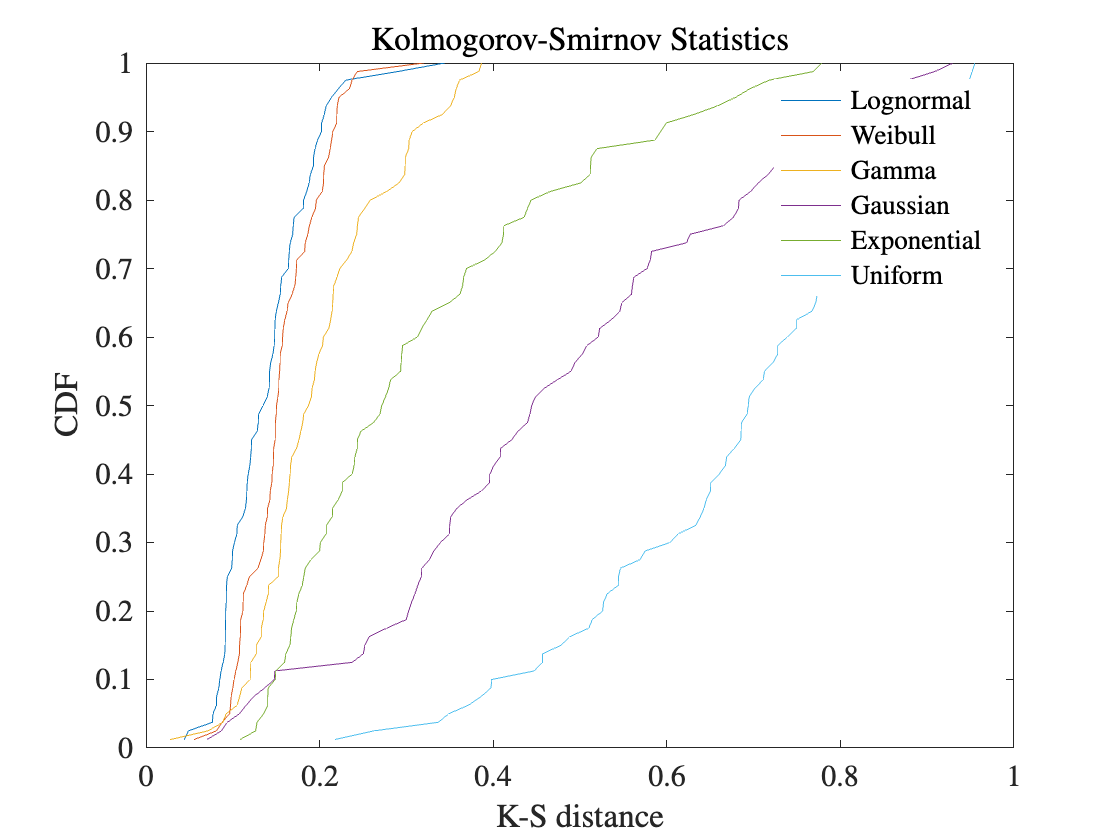

figure,
[y,x]=ecdf(tGsel_fit.ksstatL(~isnan(tGsel_fit.ksstatL)));
plot(x(2:end), y(2:end))
hold on
[y,x]=ecdf(tGsel_fit.ksstatW(~isnan(tGsel_fit.ksstatW)));
plot(x(2:end), y(2:end))
hold on
[y,x]=ecdf(tGsel_fit.ksstatG(~isnan(tGsel_fit.ksstatG)));
plot(x(2:end), y(2:end))
hold on
[y,x]=ecdf(tGsel_fit.ksstatN(~isnan(tGsel_fit.ksstatN)));
plot(x(2:end), y(2:end))
hold on
[y,x]=ecdf(tGsel_fit.ksstatE(~isnan(tGsel_fit.ksstatE)));
plot(x(2:end), y(2:end))
hold on
[y,x]=ecdf(tGsel_fit.ksstatU(~isnan(tGsel_fit.ksstatU)));
plot(x(2:end), y(2:end))
xlabel("K-S distance")
ylabel("CDF")

legend({"Lognormal", "Weibull", "Gamma", "Gaussian", "Exponential", "Uniform"})
title("Kolmogorov-Smirnov Statistics")
set(gca, 'FontSize', 15)
legend('boxoff')

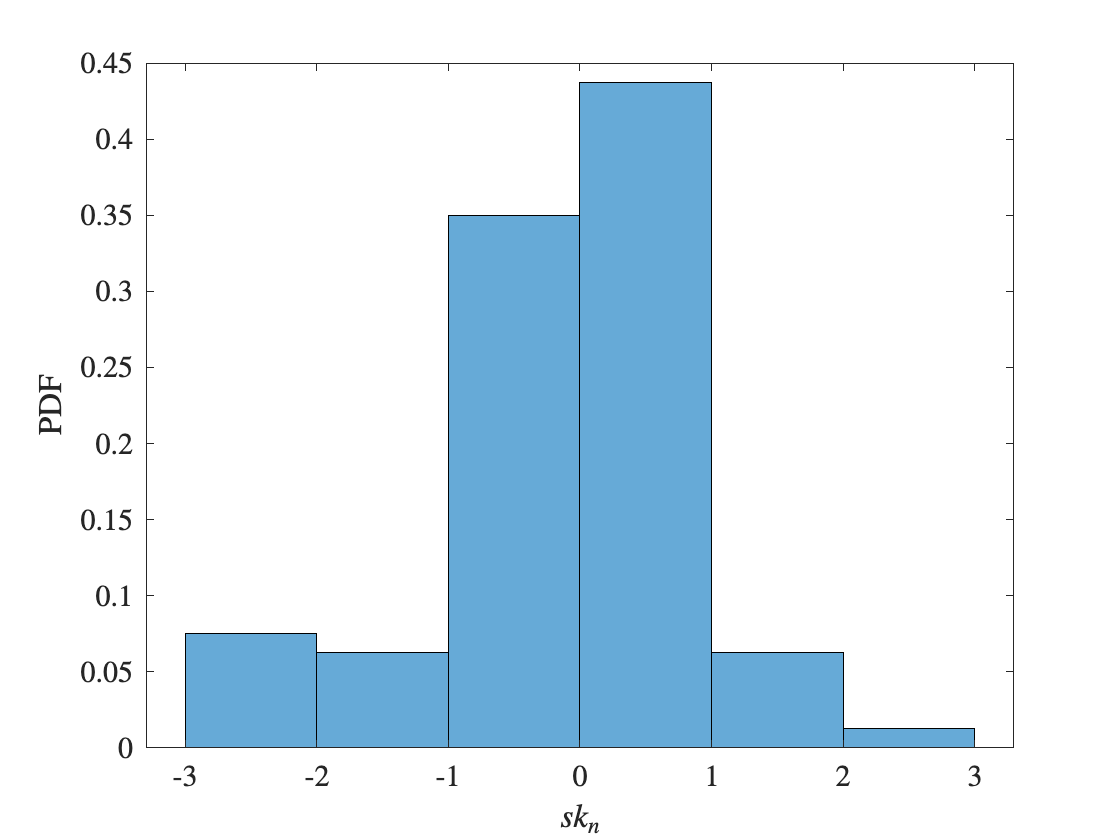

% skewness distribution
figure,
histogram(tGsel_skew.sk, 'Normalization', 'PDF')
xlabel('$sk_n$')
ylabel('PDF')
set(gca, 'FontSize', 15)

Comparison with the Logarithmic Standard Deviation in Nutrients

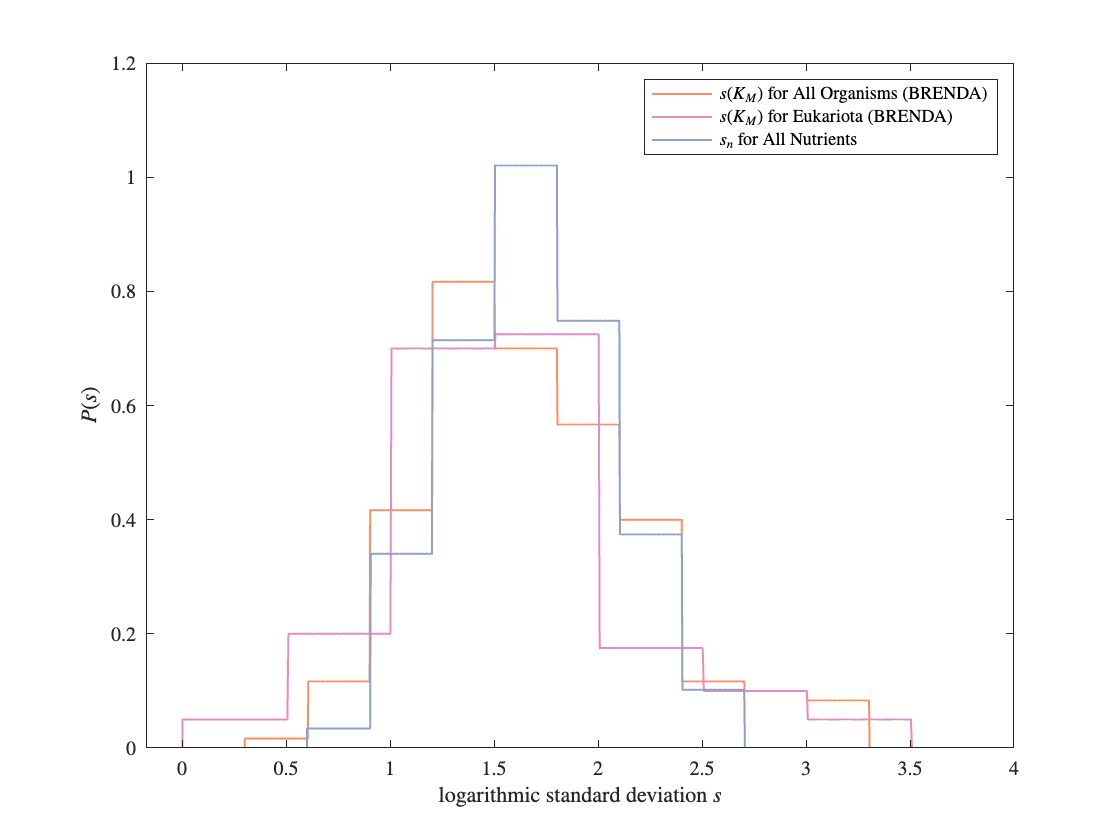

load('nutrientsLogSD')
label="Water";
tlogSD(strcmpi(label, tlogSD.Nutrient_description),:) = [];


figure,
    h=histogram(tGselAll.stdlog(tGselAll.numorganisms>=no), 'Normalization', 'PDF');
    hold on
    h.EdgeColor='None';
    h.FaceColor='None';
    h.HandleVisibility='off';
    contourhist(h,'LineWidth', 1, 'Color', [0.9882352941176471, 0.5529411764705883, 0.3843137254901961]);
    hold on
    
    h=histogram(tGselEuK.stdlog(tGselEuK.numorganisms>=no), 'Normalization', 'PDF');
    hold on
    h.EdgeColor='None';
    h.FaceColor='None';
    h.HandleVisibility='off';
    contourhist(h,'LineWidth', 1, 'Color', [0.9058823529411765, 0.5411764705882353, 0.7647058823529411]);
    hold on    
    
    h=histogram(tlogSD.sd, 'Normalization', 'PDF');
    hold on
    h.EdgeColor='None';
    h.FaceColor='None';
    h.HandleVisibility='off';
    contourhist(h,'LineWidth', 1,'Color', [0.5529411764705883, 0.6274509803921569, 0.796078431372549]);
    hold on       
    
    xlabel('logarithmic standard deviation $s$')
    ylabel('$P(s)$')

legend('$s(K_M)$ for All Organisms (BRENDA)', '$s(K_M)$ for Eukariota (BRENDA)', '$s_n$ for All Nutrients')

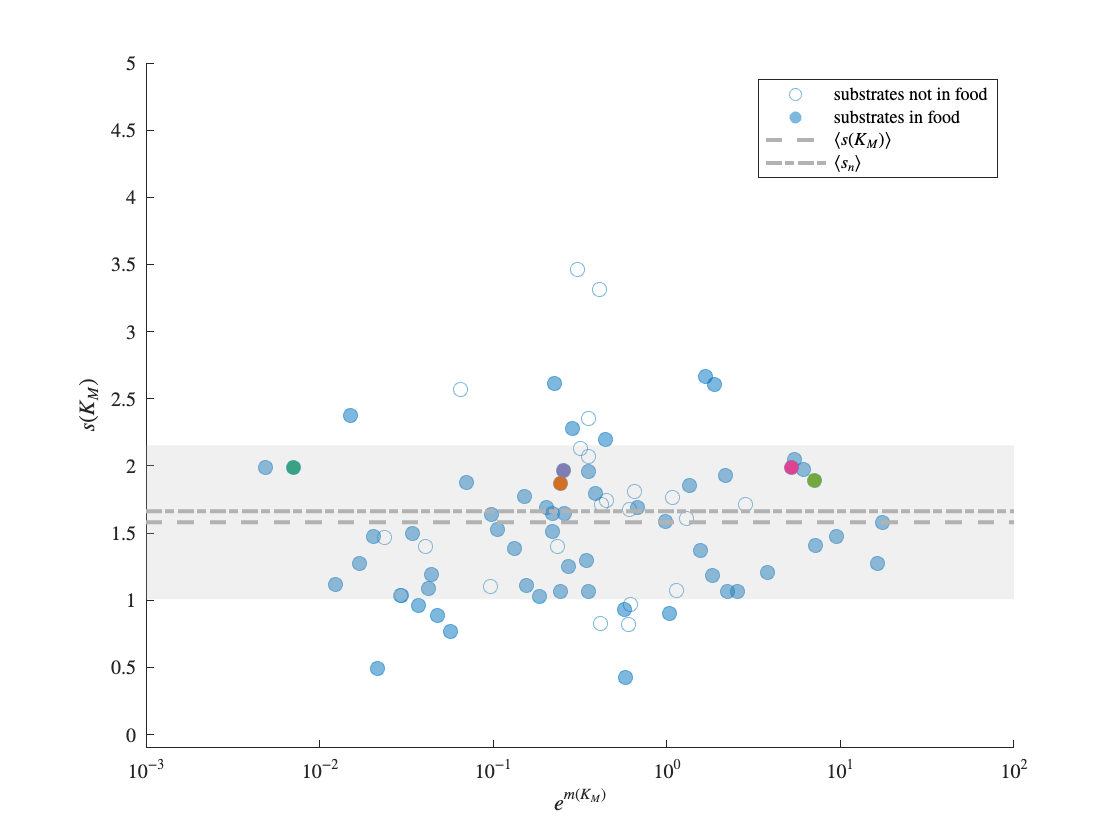

% substrates in food
cinf=unique(lower(cellstr(dballannotations.substrate(dballannotations.inFood=='True'))));
flagTGSEL=ismember(lower(cellstr(tGsel.substrate)), cinf);
newdb=tGsel(and(flagTGSEL, tGsel.numorganisms>=no), :);


% picture for paper
xl=[10^(-3),10^(-2),10^(-1), 10^0 , 10^1, 10^2];
lxl=log(xl);
figure,
h=scatter(tGsel.meanlog(tGsel.numorganisms>=no),tGsel.stdlog(tGsel.numorganisms>=no),50);
h.MarkerEdgeAlpha=0.5;
hold on
h1=scatter(newdb.meanlog,newdb.stdlog,50,'filled');
h1.CData=h.CData;
h1.MarkerFaceAlpha=0.5;
h1.MarkerEdgeAlpha=0.5;


hold on
ECsel='4.1.2.13';
SubstrateSel='D-fructose 1,6-bisphosphate';
tentry=tGsel((tGsel.EC==ECsel)&(tGsel.substrate==SubstrateSel),:);
scatter(tentry.meanlog(1),tentry.stdlog(1),50,hex2rgb('#1b9e77'),'filled','HandleVisibility','off');


hold on
ECsel='1.10.3.2';
SubstrateSel='2,6-dimethoxyphenol';
tentry=tGsel((tGsel.EC==ECsel)&(tGsel.substrate==SubstrateSel),:);
scatter(tentry.meanlog(1),tentry.stdlog(1),50,hex2rgb('#d95f02'),'filled','HandleVisibility','off');


hold on
ECsel='1.11.1.7';
SubstrateSel='H2O2';
tentry=tGsel((tGsel.EC==ECsel)&(tGsel.substrate==SubstrateSel),:);
scatter(tentry.meanlog(1),tentry.stdlog(1),50, hex2rgb('#7570b3'),'filled','HandleVisibility','off');




hold on
ECsel='1.1.1.1';
SubstrateSel='ethanol';
tentry=tGsel((tGsel.EC==ECsel)&(tGsel.substrate==SubstrateSel),:);
scatter(tentry.meanlog(1),tentry.stdlog(1),50, hex2rgb('#e7298a'),'filled','HandleVisibility','off');


hold on
ECsel='3.2.1.26';
SubstrateSel='sucrose';
tentry=tGsel((tGsel.EC==ECsel)&(tGsel.substrate==SubstrateSel),:);
scatter(tentry.meanlog(1),tentry.stdlog(1),50, hex2rgb('#66a61e'),'filled','HandleVisibility','off');


xlabel('$e^{m(K_M)}$')
ylabel('$s(K_M)$')


hold on
M=mean(tGsel.stdlog(tGsel.numorganisms>=no));
S=std(tGsel.stdlog(tGsel.numorganisms>=no));
x=lxl(1):0.001:lxl(end);
Xconf=[x x(end:-1:1)];
msk=M*ones(1,length(x));
mskl=(M-S)*ones(1,length(x));
msku=(M+S)*ones(1,length(x));
Yconf=[msku, mskl(end:-1:1)];
 
p = fill(Xconf,Yconf,[178 178 178]/255,'HandleVisibility','off');
p.FaceAlpha=0.2;     
p.EdgeColor = 'none';     
hold on
pp=plot(x, msk, '--', 'LineWidth', 2, 'Color', [178 178 178]/255);


hold on
pp=plot(x, mean(tlogSD.sd)*ones(1,length(x)), '-.', 'LineWidth', 2, 'Color', [178 178 178]/255);
hold on



ax = gca;
ax.TickLabelInterpreter  = 'latex';   
 
xticks(lxl)
xticklabels({'$10^{-3}$','$10^{-2}$','$10^{-1}$', '$10^{0}$', '$10^{1}$','$10^{2}$'})
axis([lxl(1) lxl(end) -0.1 5])
hold on
legend('substrates not in food', 'substrates in food', '$\langle s(K_M) \rangle$', '$\langle s_n \rangle$')

Collapsing of the pdf curves

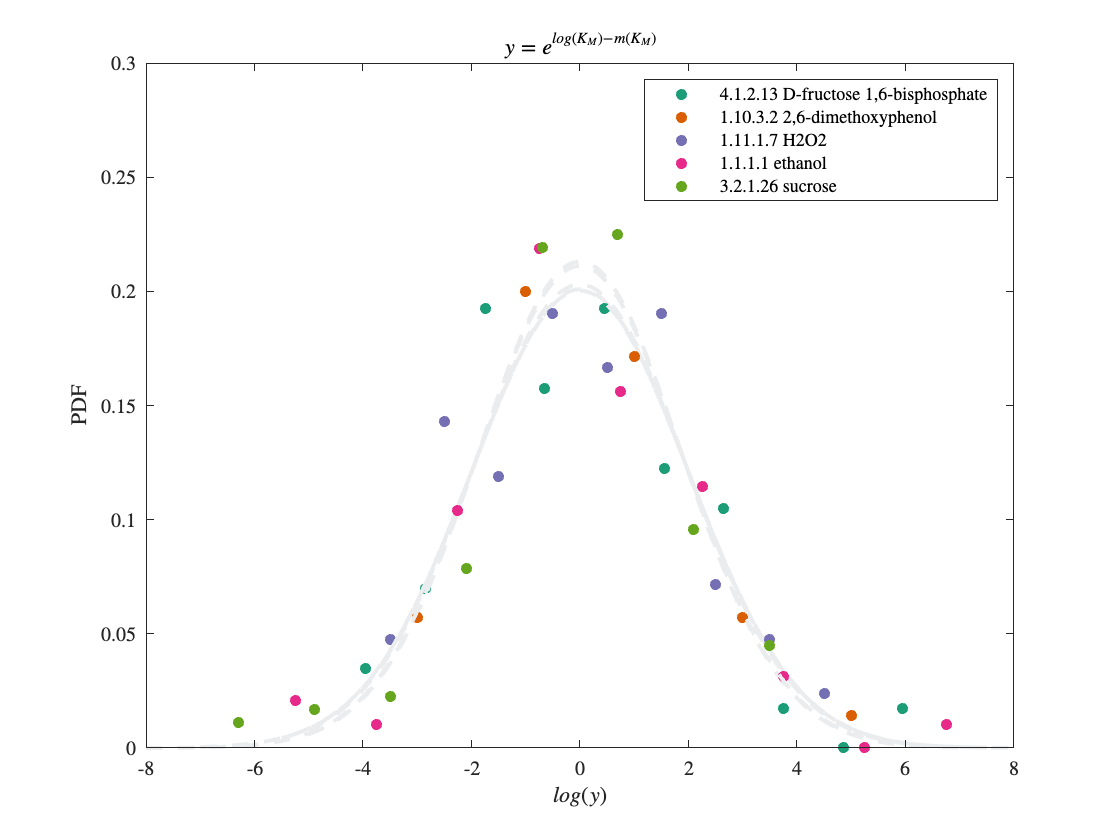

% paper picture collapse
xl=[10^(-5),10^(-4),10^(-3),10^(-2),10^(-1), 10^0 , 10^1, 10^2,  10^3,  10^4];
lxl=log(xl);
vcell={};

lb={};
figure,
ECsel='4.1.2.13';
SubstrateSel='D-fructose 1,6-bisphosphate';
db2plot=db((db.EC==ECsel)&(db.substrate==SubstrateSel),:);
mv=mean(db2plot.logKM);
v=db2plot.logKM-mv;
vcell{1}=v;

h=histogram(v, 'Normalization', 'PDF','EdgeAlpha', 1, 'FaceAlpha', 0.3,  'NumBins', 10 );
lb=[lb,[ECsel, ' ', SubstrateSel]];
hold on
centers=h.BinEdges+h.BinWidth/2;
centers=centers(1:end-1);
pdfvalues=h.Values;
hold on
[p1,p2]=normfit(v);
x=linspace(-1+min(h.BinEdges), 1+max(h.BinEdges),5000);
y=normpdf(x, p1,p2);
plot(x,y,'--','color', [234, 236, 238]/255,'HandleVisibility','off', 'LineWidth',2)
hold on
delete(h)
plot(centers, pdfvalues,'x', 'Color', '#1b9e77','marker', 'o', 'LineStyle', 'none', 'MarkerSize', 5, 'MarkerFaceColor' ,  '#1b9e77')
hold on




ECsel='1.10.3.2';
SubstrateSel='2,6-dimethoxyphenol';
db2plot=db((db.EC==ECsel)&(db.substrate==SubstrateSel),:);
mv=mean(db2plot.logKM);
v=db2plot.logKM-mv;
vcell{2}=v;

h=histogram(v, 'Normalization', 'PDF','EdgeAlpha', 1, 'FaceAlpha', 0.3);
lb=[lb,[ECsel, ' ', SubstrateSel]];
hold on
centers=h.BinEdges+h.BinWidth/2;
centers=centers(1:end-1);
pdfvalues=h.Values;
hold on
[p1,p2]=normfit(v);
x=linspace(-1+min(h.BinEdges), 1+max(h.BinEdges),5000);
y=normpdf(x, p1,p2);
plot(x,y,'--','color', [234, 236, 238]/255,'HandleVisibility','off', 'LineWidth',2)
hold on
delete(h)
plot(centers, pdfvalues,'x', 'Color', '#d95f02','marker', 'o', 'LineStyle', 'none', 'MarkerSize', 5, 'MarkerFaceColor' ,  '#d95f02')
hold on


ECsel='1.11.1.7';
SubstrateSel='H2O2';
db2plot=db((db.EC==ECsel)&(db.substrate==SubstrateSel),:);
mv=mean(db2plot.logKM);
v=db2plot.logKM-mv;
vcell{3}=v;

h=histogram(v, 'Normalization', 'PDF','EdgeAlpha', 1, 'FaceAlpha', 0.3,  'NumBins',9);
lb=[lb,[ECsel, ' ', SubstrateSel]];
hold on
centers=h.BinEdges+h.BinWidth/2;
centers=centers(1:end-1);
pdfvalues=h.Values;
hold on
[p1,p2]=normfit(v);
x=linspace(-1+min(h.BinEdges), 1+max(h.BinEdges),5000);
y=normpdf(x, p1,p2);
plot(x,y,'--','color', [234, 236, 238]/255,'HandleVisibility','off', 'LineWidth',2)
hold on
delete(h)
plot(centers, pdfvalues,'x', 'Color', '#7570b3','marker', 'o', 'LineStyle', 'none', 'MarkerSize', 5, 'MarkerFaceColor' ,  '#7570b3')
hold on



ECsel='1.1.1.1';
SubstrateSel='ethanol';
db2plot=db((db.EC==ECsel)&(db.substrate==SubstrateSel),:);
mv=mean(db2plot.logKM);
v=db2plot.logKM-mv;
vcell{4}=v;

h=histogram(v, 'Normalization', 'PDF','EdgeAlpha', 1, 'FaceAlpha', 0.3,  'NumBins', 9);
lb=[lb,[ECsel, ' ', SubstrateSel]];
hold on
centers=h.BinEdges+h.BinWidth/2;
centers=centers(1:end-1);
pdfvalues=h.Values;
hold on
[p1,p2]=normfit(v);
x=linspace(-1+min(h.BinEdges), 1+max(h.BinEdges),5000);
y=normpdf(x, p1,p2);
plot(x,y,'--','color', [234, 236, 238]/255,'HandleVisibility','off', 'LineWidth',2)
hold on
delete(h)
plot(centers, pdfvalues,'x', 'Color', '#e7298a','marker', 'o', 'LineStyle', 'none', 'MarkerSize', 5, 'MarkerFaceColor' ,  '#e7298a')
hold on



ECsel='3.2.1.26';
SubstrateSel='sucrose';
db2plot=db((db.EC==ECsel)&(db.substrate==SubstrateSel),:);
mv=mean(db2plot.logKM);
v=db2plot.logKM-mv;
vcell{5}=v;

h=histogram(v, 'Normalization', 'PDF','EdgeAlpha', 1, 'FaceAlpha', 0.3, 'NumBins',8 );
lb=[lb,[ECsel, ' ', SubstrateSel]];
hold on
centers=h.BinEdges+h.BinWidth/2;
centers=centers(1:end-1);
pdfvalues=h.Values;
hold on
[p1,p2]=normfit(v);
x=linspace(-1+min(h.BinEdges), 1+max(h.BinEdges),5000);
y=normpdf(x, p1,p2);
plot(x,y,'--','color', [234, 236, 238]/255,'HandleVisibility','off', 'LineWidth',2)
hold on
delete(h)
plot(centers, pdfvalues,'x', 'Color', '#66a61e','marker', 'o', 'LineStyle', 'none', 'MarkerSize', 5, 'MarkerFaceColor' ,  '#66a61e')
hold on



legend(lb)


xlabel('$log(y)$')
ylabel('PDF')
title('$y=e^{log(K_M)-m(K_M)}$')
axis([-8 8 0 0.3])

Logarithmic Standard deviation for chemicals in food

% older figure but only for chemicals in the food database
cinf=unique(lower(cellstr(dballannotations.substrate(dballannotations.inFood=='True'))));


figure,
title('Only chemicals in food')
hold on
    flagTGSEL=ismember(lower(cellstr(tGselAll.substrate)), cinf);
    newdb=tGselAll(and(flagTGSEL, tGselAll.numorganisms>=no), :);
    h=histogram(newdb.stdlog, 'Normalization', 'PDF');
    hold on
    h.EdgeColor='None';
    h.FaceColor='None';
    h.HandleVisibility='off';
    contourhist(h,'LineWidth', 1, 'Color', [0.9882352941176471, 0.5529411764705883, 0.3843137254901961]);
    hold on
    
    disp('Number of (substrate, EC) pairs in all organisms, with the substrate belonging to the food database')

Number of (substrate, EC) pairs in all organisms, with the substrate belonging to the food database


    disp(height(newdb))

   137



    

    flagTGSEL=ismember(lower(cellstr(tGselEuK.substrate)), cinf);
    newdb=tGselEuK(and(flagTGSEL, tGselEuK.numorganisms>=no), :);
    h=histogram(newdb.stdlog, 'Normalization', 'PDF');
    hold on
    h.EdgeColor='None';
    h.FaceColor='None';
    h.HandleVisibility='off';
    contourhist(h,'LineWidth', 1, 'Color', [0.9058823529411765, 0.5411764705882353, 0.7647058823529411]);
    hold on    
    
    disp('Number of (substrate, EC) pairs in eukariotes, with the substrate belonging to the food database')

Number of (substrate, EC) pairs in eukariotes, with the substrate belonging to the food database


    disp(height(newdb))

    58



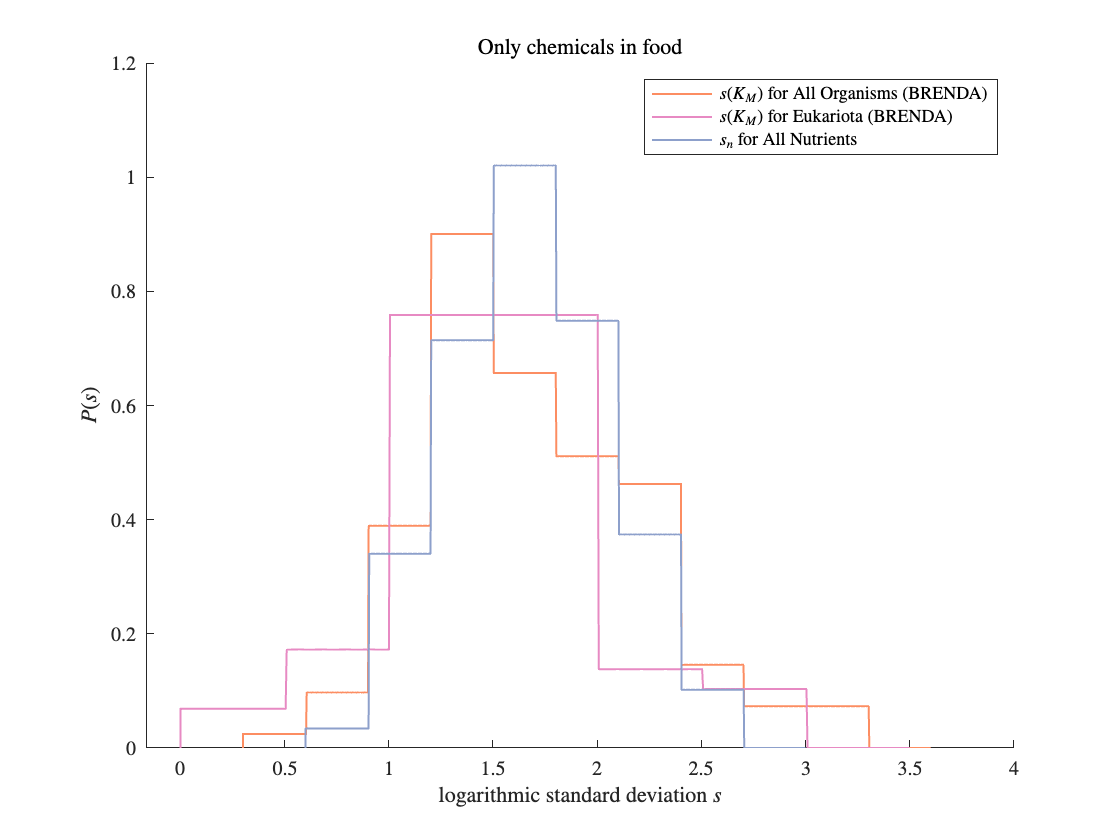

    
    h=histogram(tlogSD.sd, 'Normalization', 'PDF');
    hold on
    h.EdgeColor='None';
    h.FaceColor='None';
    h.HandleVisibility='off';
    contourhist(h,'LineWidth', 1,'Color', [0.5529411764705883, 0.6274509803921569, 0.796078431372549]);
    hold on       
    
    xlabel('logarithmic standard deviation $s$')
    ylabel('$P(s)$')

legend('$s(K_M)$ for All Organisms (BRENDA)', '$s(K_M)$ for Eukariota (BRENDA)', '$s_n$ for All Nutrients')